# Combustion Engine

Version: 0.0

This version contains the model for an *idealized* cycle running on *gasoline*.

## General

clear all;
close all;
clc;

%Add difference path folders
relativepath_to_generalfolder = 'General';
addpath(relativepath_to_generalfolder);
relativepath_to_nasafolder = 'Nasa';
addpath(relativepath_to_nasafolder);
relativepath_to_functionsfolder = 'Functions';
addpath(relativepath_to_functionsfolder);

%Load Nasa Database
TdataBase = fullfile('Nasa','NasaThermalDatabase.mat');
load(TdataBase);

### Constants 

global Runiv Pref Tref                  %Set global variables (so they cannot be changed)
Runiv = 8.314472;                       %Universal Gas Constant[J/K*mol]
Pref = 1.01235e5;                       %Reference Pressure (1atm) [Pa]
Tref = 298.15;                          %Reference Temperature [K]

%Starting with only Gasoline
Species = Sp(myfind({Sp.Name},{'Gasoline','O2','CO2','H2O','N2'})); %Subselection of species in database
Mi = [Species.Mass];                    %Array of molecular masses for each component
n_Nitr = (25*0.79)/(0.21);              %No. moles nitrogen using air composition (79%)

%Calculate gas compositions of reactants and products using balanced
%chemical equation
X_reac = [2/(2+25+n_Nitr) 25/(2+25+n_Nitr) 0 0 n_Nitr/(2+25+n_Nitr)];
X_prod = [0 0 16/(16+18+n_Nitr) 18/(16+18+n_Nitr) n_Nitr/(16+18+n_Nitr)];

%Convert to mass fractions
Y_reac = (X_reac.*Mi)/(X_reac*Mi');
Y_prod = (X_prod.*Mi)/(X_prod*Mi');

%Molar mass
M_reac = X_reac*Mi';
M_prod = X_prod*Mi';

%Gas constants
R_reac = Runiv/M_reac;
R_prod = Runiv/M_prod;

### Dimensions

B = 2e-2;                               %Bore [m]
r = 1e-2;                               %Radius of crank shaft [m]
S = 2*r;                                %Stroke [m]
L = 5e-2;                               %Length of rod [m]
V_c = (5e-2)^3;                         %Clearance volume [m^3]

## Idealized Cycle

Assumptions:

- Both intake and exhaust gases are *ideal gases* and are at *atmospheric pressure*

- *Adiabatic *compression

- *Isochoric *and *Instantaneous *combustion

- *Adiabatic *expansion

- *Isochoric *exhaust 

- *Isothermal/Isobaric *exhaust/intake stroke

p_ideal = [];
V_ideal = [];
T_ideal = [];
theta_crank = [];

p1 = Pref;
V1 = Vcyl(0,B,r,L,V_c);
T1 = Tref;

for i = 1:length(Species)
    h1_i(i) = HNasa(T1,Species(i));
    s1_i(i) = SNasa(T1,Species(i));
end
s1_thermal = Y_reac*s1_i';
s_1 = s1_thermal - R_reac*log(p1/Pref);
h_1 = Y_reac*h1_i';

m = (p1*V1)/(R_reac*T1)';
S1 = s_1*m;
H_1 = h_1*m;

p_ideal(1) = p1;
T_ideal(1) = T1;
V_ideal(1) = V1;
theta_crank(1) = 0;

dt = 0.0001;
dthetadt = 3000/60*2*pi

dthetadt = 314.1593

time = [0:dt:2*(60/(3000))]; %One rotation takes 0.02 seconds however, one cycle is two revolutions

i = 1;

for t = [dt:dt:2*(60/(3000))]
    i = i+1;
    theta_crank(i) = theta_crank(i-1)+dt*dthetadt;
    V_ideal(i) = Vcyl(theta_crank(i),B,r,L,V_c);
end

theta_crank_degrees = theta_crank.*(180/pi);

intake_stroke_start_theta = 0;
compression_start_theta = 180;
ignition_start_theta = 360;
expansion_start_theta = 360;
valve_exhaust_start_theta = 540;
exhaust_stroke_start_theta = 540;

intake_stroke_index = max(find(theta_crank_degrees==intake_stroke_start_theta));
compression_start_index = max(find(theta_crank_degrees<compression_start_theta));
ignition_start_index = max(find(theta_crank_degrees<ignition_start_theta));
expansion_start_index = max(find(theta_crank_degrees<expansion_start_theta));
valve_exhaust_start_index = max(find(theta_crank_degrees<valve_exhaust_start_theta));
exhaust_stroke_start_index = max(find(theta_crank_degrees<exhaust_stroke_start_theta));

intake_stroke_start_time = time(intake_stroke_index);
compression_start_time = time(compression_start_index);
ignition_start_time = time(ignition_start_index);
expansion_start_time = time(expansion_start_index);
valve_exhaust_start_time = time(valve_exhaust_start_index);
exhaust_stroke_start_time = time(exhaust_stroke_start_index);



### Intake Stroke

i = 0;
for t = [intake_stroke_start_time:dt:compression_start_time]
    i = i+1;
    p_ideal(i) = Pref;
    T_ideal(i) = Tref;
end


### Compression

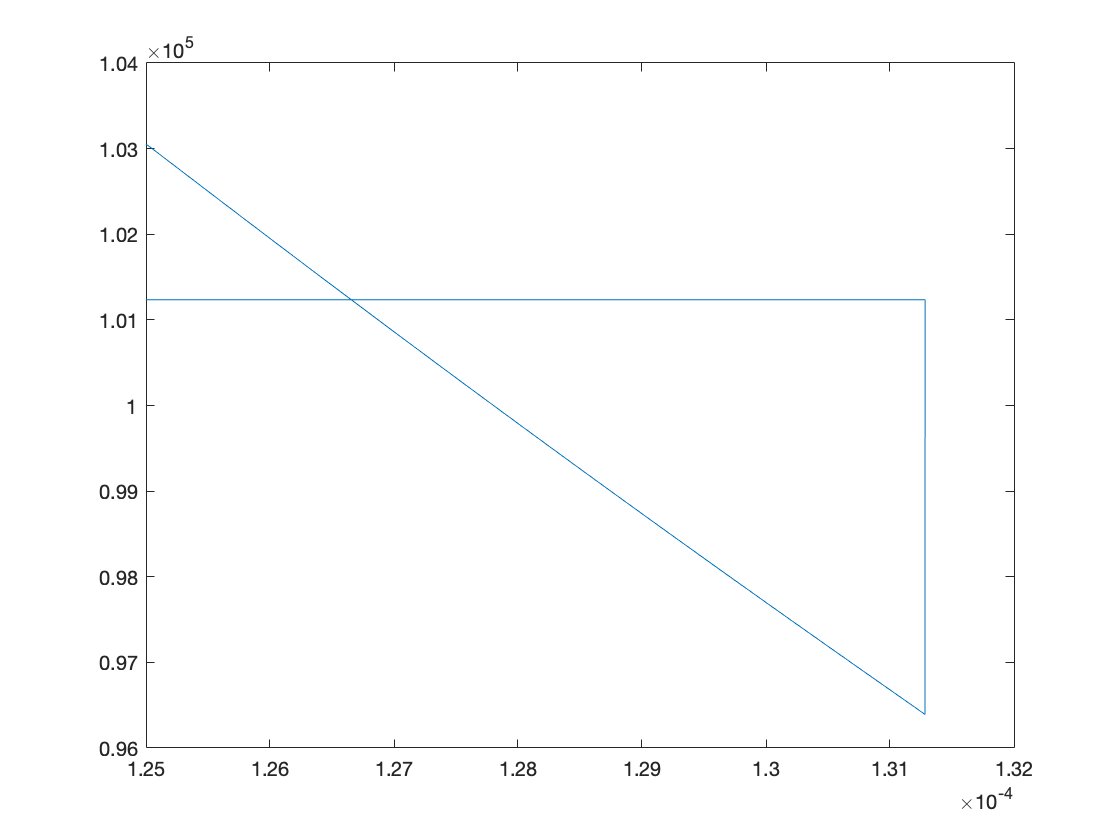

for t = [compression_start_time:dt:ignition_start_time]
    i = i+1;
    for j = [1:length(Species)]
        cvj(j) = CvNasa(T_ideal(i-1),Species(j));
    end
    
    Cv = Y_reac*cvj';

    dTdt = -(R_reac*T_ideal(i-1))/(V_ideal(i-1)*Cv)*dVdt(theta_crank(i),dthetadt,B,r,L);

    T_ideal(i)= T_ideal(i-1)+dt*dTdt;
    p_ideal(i)= (m*R_reac*T_ideal(i))/(V_ideal(i));
end

plot(V_ideal(1:i),p_ideal)

### Ignition

### Power Stroke 

### Valve Exhaust

### Exhaust Stroke

### Intake Stroke

## Functions

function [Vcyl] = Vcyl(theta,B,r,L,V_c)
%This function is used to calculate the volume of the cylinder 
%   See lecture for derivation of formula

x = r*cos(theta)+sqrt(L^2-r^2*sin(theta)^2);                                %Distance from center of crankshaft to center of piston head

d = L+r-x;                                                                  %Distance of top of piston head to its maximum height

Vcyl = pi/4*B^2*d+V_c;

end

function [dVdt] = dVdt(theta,dthetadt,B,r,L)
    dVdt = pi/4*B^2*(dthetadt*r*sin(theta)+0.5*(dthetadt*r^2*sin(2*theta))/(sqrt(L^2-0.5*r^2*(1-cos(2*theta)))));
end